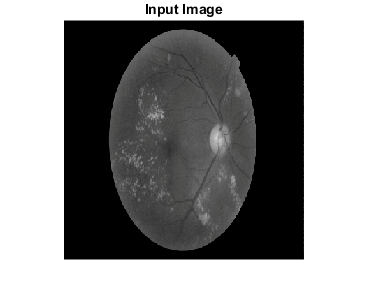

%Histograms
input_image = imread('HE_Input1.png');
image = input_image;
imshow(image);
title('Input Image');


mean_input = mean(input_image(:));
disp("Mean Grayscale level of input image is: " + mean_input);

Mean Grayscale level of input image is: 37.0019


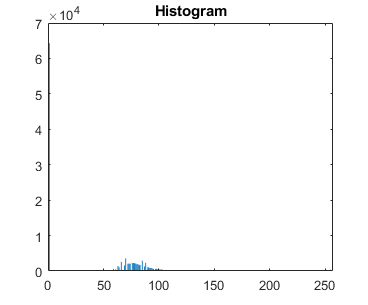


[height, width, num_color_channel] = size(input_image);

if num_color_channel > 1
  %disp(numColorChannel);
  image = rgb2gray(input_image);
end 

hist_input_image = reg_histogram(image, 'Histogram');

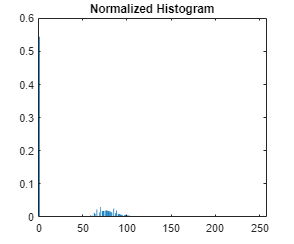

prob_input_image = normalized_histogram(hist_input_image, image, 'Normalized Histogram');

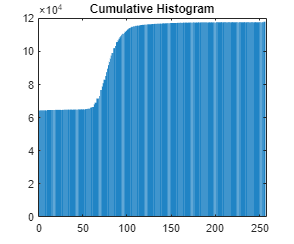

cumulative_input_image = cumulative_histogram(hist_input_image, 'Cumulative Histogram');

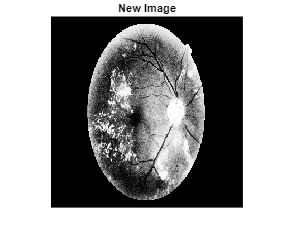


map = uint8(zeros(size(image, 1), size(image, 2)));
pixels_in_image = size(image, 1) * size(image, 2);

for i = 1:256
    map = round(((cumulative_input_image - min(cumulative_input_image))/(pixels_in_image - min(cumulative_input_image)))* 255);
end

new_image = uint8(zeros(size(image, 1), size(image, 2)));
for i = 1:height
    for j = 1:width
        new_image(i,j)=map(image(i,j) + 1);
    end
end

imshow(new_image);
title('New Image');

mean_new_image = mean(new_image(:));
disp("Mean Grayscale level of input image is: " + mean_new_image);

Mean Grayscale level of input image is: 59.8616


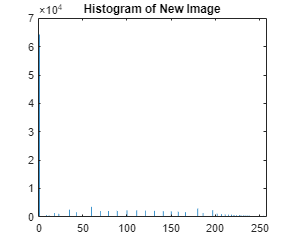


hist_new_image = reg_histogram(new_image, 'Histogram of New Image');

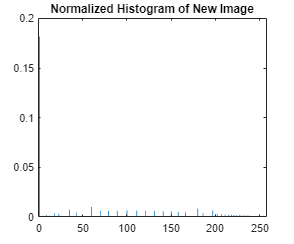

prob_new_image = normalized_histogram(hist_new_image, input_image, 'Normalized Histogram of New Image');

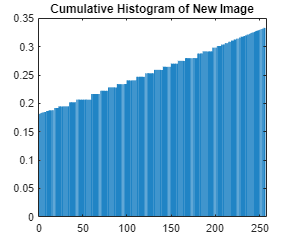

cumulative_new_image = cumulative_histogram(prob_new_image, 'Cumulative Histogram of New Image');


%Message Entropy
string = 'probablisi systems analysis is the best class that engineers walking the mean streetz can take';

if (ischar(string) == 1)    
    l = length(string);
    unique_char = unique(string);   
    len_char = length(unique_char);

    f = zeros(1, len_char);
    for i=1:len_char
        f(i)=length(strfind(string,unique_char(i)));
    end

    p = zeros(1, len_char);
    for i=1:len_char
        p(i) = f(i) / l; 
    end

    entropy = 0;
    for  i=1:len_char
        entropy = entropy + (-p(i) * log2(p(i)));
    end 
else
    disp('Invalid String');
end

ascii_dec = double(string);
ascii_binary = dec2bin(ascii_dec);
ascii_binary_len = length(ascii_binary);

disp("The message entropy is " + entropy);

The message entropy is 3.8448


disp("Length of the string: " + l);

Length of the string: 94


disp("The ASCII is the same length as the array: "+ ascii_binary_len);

The ASCII is the same length as the array: 94



%Kullback Leibler Divergence
if size(cumulative_input_image,2)~=size(cumulative_new_image,2)
    error('the number of columns in P and Q should be the same');
end
if sum(~isfinite(cumulative_input_image(:))), sum(~isfinite(cumulative_new_image(:)))
   error('the inputs contain non-finite values!') 
end
% normalizing the P and Q
if size(cumulative_input_image,1) == 1
    cumulative_input_image = cumulative_input_image ./sum(cumulative_input_image);
    cumulative_new_image = cumulative_new_image ./repmat(sum(cumulative_new_image,2),[1 size(cumulative_new_image,2)]);
    temp =  cumulative_new_image.*log(cumulative_new_image./repmat(cumulative_input_image,[size(cumulative_new_image,1) 1]));
    temp(isnan(temp)) = 0;
    dist = sum(temp,2);
    
elseif size(cumulative_input_image,1)==size(cumulative_new_image,1)
    cumulative_input_image = cumulative_input_image./repmat(sum(cumulative_input_image,2),[1 size(cumulative_input_image,2)]);
    cumulative_new_image = cumulative_new_image./repmat(sum(cumulative_new_image,2),[1 size(cumulative_new_image,2)]);
    temp =  cumulative_new_image.*log(cumulative_new_image./cumulative_input_image);
    temp(isnan(temp)) = 0;
    dist = sum(temp,2);
end

disp("The Kullback Leibler Divergence is: " + dist);

The Kullback Leibler Divergence is: 0.0078795


function f = reg_histogram(image,imageTitle)
[height,width]=size(image);

pixel = zeros(1,256);
for i = 1:height
    for j = 1:width
        pixel(image(i,j) + 1) = pixel(image(i,j) + 1) + 1;
    end
end

bar(pixel)
title(imageTitle);

f = pixel;
end

function f = normalized_histogram(num_pixel,image,title0)
[height,width]=size(image);

pixel = zeros(1,256);
for i = 1:256
    pixel(i) = num_pixel(i) / (height * width * 1.0);
end

bar(pixel)
title(title0);

f = pixel;
end

function f = cumulative_histogram(prob_pixel,title0)
pixel = zeros(1,256);
for i = 1:256
    if i == 1
        pixel(i) = prob_pixel(i);
    else
        pixel(i) = pixel(i-1) + prob_pixel(i);
    end
end

bar(pixel)
title(title0);

f = pixel;
end